# 脉冲压缩

脉冲压缩的一个量化量度是压缩比，其为初始信号长度除以压缩脉冲的3dB宽度(也就是分辨率)，接近未压缩脉冲的TBP。线性调频脉冲的压缩比可达几百甚至几千的量级。

## 线性调频信号的时域匹配滤波器

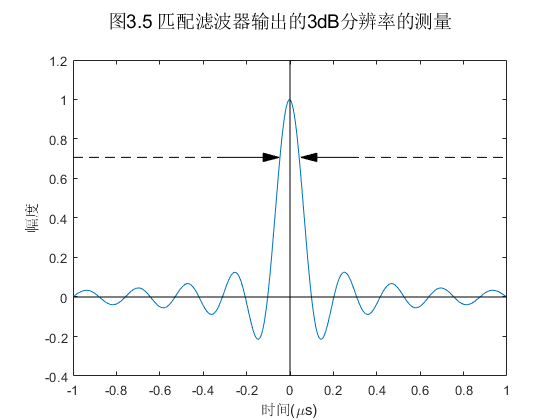

% 参数设置
TBP = 100;             % 时间带宽积
T = 10e-6;             % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 50;         % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
t_out = linspace(2*t(1),2*t(end),2*length(t)-1);    % 循环卷积后的信号长度    
% 信号表达
st = exp(1j*pi*K*t.^2);               % Chirp信号复数表达式
ht = conj(fliplr(st));                % 时域匹配滤波器
sout = conv(st,ht);                   % 匹配滤波器输出
sout = sout/max(sout);                % 归一化
% 绘图
figure
plot(t_out*1e+6,real(sout))
axis([-1 1,-0.4 1.2])
xlabel('时间(\mus)'),ylabel('幅度')
line([-1,1],[ 0,  0],'Color','k')
line([ 0,0],[-0.4,1.2],'Color','k')
line([-1,-0.05],[0.707,0.707],'Color','k','LineStyle','--')
line([ 0.05, 1],[0.707,0.707],'Color','k','LineStyle','--')
arrow([-0.3,0.707],[-0.05,0.707]);
arrow([ 0.3,0.707],[ 0.05,0.707]);
suptitle('图3.5 匹配滤波器输出的3dB分辨率的测量')

**疑问：**当采样点数较低时，匹配滤波器输出的中心点不在时间零点(采样点数越小，匹配滤波器输出的中心点向左偏移)，这是为什么？以及书上说的插值后的匹配滤波器输出是什么意思?

#### 基带线性调频信号的匹配滤波

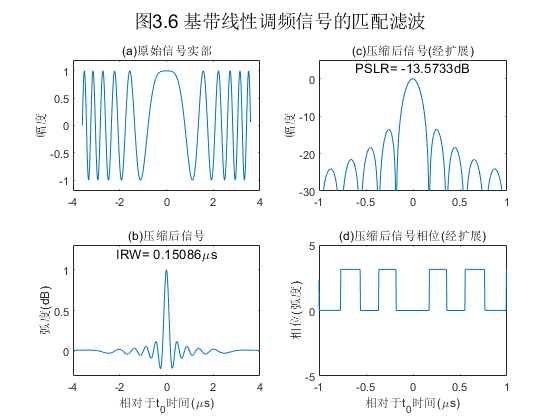

% 参数设置
TBP = 42;              % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 50;         % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
t_out = linspace(2*t(1),2*t(end),2*length(t)-1);    % 循环卷积后的信号长度    
% 信号表达
st = exp(1j*pi*K*t.^2);               % Chirp信号复数表达式
ht = conj(fliplr(st));                % 时域匹配滤波器
sout = conv(st,ht);                   % 匹配滤波器输出
% figure
% plot(t_out*1e+6,real(sout))
% 信号变换
sout_nor = sout/max(sout);                          % 单位化
sout_log = 20*log10(abs(sout)./max(abs(sout))+eps); % 归一化
% 绘图
figure
subplot(221),plot(t*1e+6,real(st))
axis([-4 4,-1.2 1.2])
title('(a)原始信号实部'),ylabel('幅度')

subplot(222),plot(t_out*1e+6,sout_log)
axis([-1 1,-30 5])
title('(c)压缩后信号(经扩展)'),ylabel('幅度')
[pslr] = get_pslr(sout_log);
text(0,3,['PSLR= ',num2str(pslr),'dB'],'HorizontalAlignment','center')

subplot(223),plot(t_out*1e+6,real(sout_nor))
axis([-4 4,-0.3 1.3])
title('(b)压缩后信号'),xlabel('相对于t_0时间(\mus)'),ylabel('弧度(dB)')
[irw,~,~] = get_irw(sout_nor);
irw = irw*dt;
text(0,1.2,['IRW= ',num2str(irw*1e+6),'\mus'],'HorizontalAlignment','center')

subplot(224),plot(t_out*1e+6,abs(angle(sout_nor)))
axis([-1 1,-5 5])
title('(d)压缩后信号相位(经扩展)'),xlabel('相对于t_0时间(\mus)'),ylabel('相位(弧度)')
suptitle('图3.6 基带线性调频信号的匹配滤波')

#### 存在噪声时基带线性调频信号的匹配滤波

设输入线性调频信号的幅度为1，匹配滤波器在频域带通内的系数为1，则匹配滤波器输出信号的峰值幅度为$\sqrt{K}T=\sqrt{TBP}$，噪声功率不变，可得信噪比提升了TBP倍。

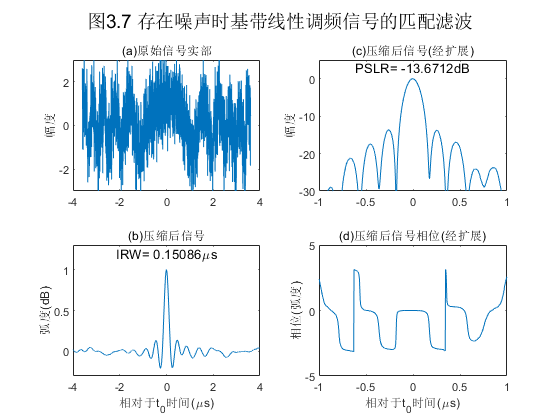

% 参数设置% 参数设置
TBP = 42;              % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 50;         % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
t_out = linspace(2*t(1),2*t(end),2*length(t)-1);    % 循环卷积后的信号长度    
% 信号表达
st = exp(1j*pi*K*t.^2);               % Chirp信号复数表达式
ht = conj(fliplr(st));                % 时域匹配滤波器
% sout = conv(st,ht);                   % 匹配滤波器输出
% 信号变换
% sout_nor = sout/max(sout);                          % 单位化
% sout_log = 20*log10(abs(sout)./max(abs(sout))+eps); % 归一化
% 在信号中加入高斯白噪声的两种方式
st_noise = awgn(st,-2.5,'measured');
% st_noise = st+0.75*1*randn(1,N);
% 信号表达
sout_noise = conv(st_noise,ht);                     % 匹配滤波器输出
% figure
% plot(t_out*1e+6,real(sout_noise))
% 信号变换
sout_noise_nor = sout_noise/max(sout_noise);                          % 单位化
sout_noise_log = 20*log10(abs(sout_noise)./max(abs(sout_noise))+eps); % 归一化
% 绘图
figure
subplot(221),plot(t*1e+6,real(st_noise))
axis([-4 4,-3 3])
title('(a)原始信号实部'),ylabel('幅度')

subplot(222),plot(t_out*1e+6,sout_noise_log)
axis([-1 1,-30 5])
title('(c)压缩后信号(经扩展)'),ylabel('幅度')
[pslr] = get_pslr(sout_noise_log);
text(0,3,['PSLR= ',num2str(pslr),'dB'],'HorizontalAlignment','center')

subplot(223),plot(t_out*1e+6,real(sout_noise_nor))
axis([-4 4,-0.3 1.3])
title('(b)压缩后信号'),xlabel('相对于t_0时间(\mus)'),ylabel('弧度(dB)')
[irw,~,~] = get_irw(sout_noise_nor);
irw = irw*dt;
text(0,1.2,['IRW= ',num2str(irw*1e+6),'\mus'],'HorizontalAlignment','center')

subplot(224),plot(t_out*1e+6,angle(sout_noise_nor))
axis([-1 1,-5 5])
title('(d)压缩后信号相位(经扩展)'),xlabel('相对于t_0时间(\mus)'),ylabel('相位(弧度)')
suptitle('图3.7 存在噪声时基带线性调频信号的匹配滤波')

#### 非基带线性调频信号的匹配滤波

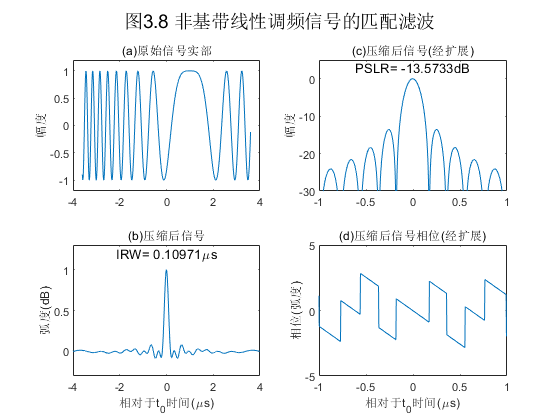

% 参数设置
TBP = 42;              % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
t_c = 1e-6;            % 时间偏移量
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 50;         % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
t_out = linspace(2*t(1),2*t(end),2*length(t)-1);    % 循环卷积后的信号长度    
% 信号表达
st = exp(1j*pi*K*(t-t_c).^2);         % Chirp信号复数表达式
ht = conj(fliplr(st));                % 时域匹配滤波器
sout = conv(st,ht);                   % 匹配滤波器输出
% 信号变换
sout_nor = sout/max(sout);                          % 单位化
sout_log = 20*log10(abs(sout)./max(abs(sout))+eps); % 归一化
% 绘图
figure
subplot(221),plot(t*1e+6,real(st))
axis([-4 4,-1.2 1.2])
title('(a)原始信号实部'),ylabel('幅度')

subplot(222),plot(t_out*1e+6,sout_log)
axis([-1 1,-30 5])
title('(c)压缩后信号(经扩展)'),ylabel('幅度')
[pslr] = get_pslr(sout_log);
text(0,3,['PSLR= ',num2str(pslr),'dB'],'HorizontalAlignment','center')

subplot(223),plot(t_out*1e+6,real(sout_nor))
axis([-4 4,-0.3 1.3])
title('(b)压缩后信号'),xlabel('相对于t_0时间(\mus)'),ylabel('弧度(dB)')
[irw,~,~] = get_irw(sout_nor);
irw = irw*dt;
text(0,1.2,['IRW= ',num2str(irw*1e+6),'\mus'],'HorizontalAlignment','center')

subplot(224),plot(t_out*1e+6,angle(sout_nor))
axis([-1 1,-5 5])
title('(d)压缩后信号相位(经扩展)'),xlabel('相对于t_0时间(\mus)'),ylabel('相位(弧度)')
suptitle('图3.8 非基带线性调频信号的匹配滤波')

通常要将压缩数据校准至零频位置，这可以通过频域中的匹配滤波器很方便地实现。

#### 存在噪声非基带线性调频信号的匹配滤波

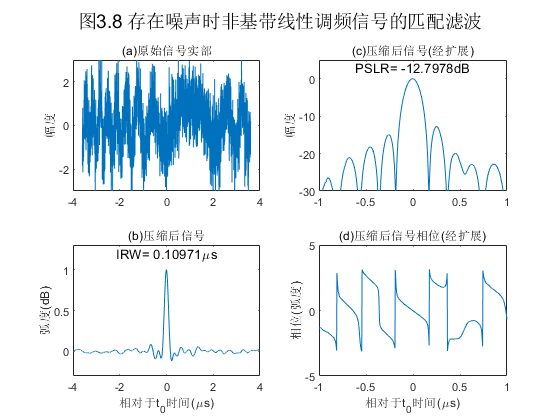

% 参数设置
TBP = 42;              % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
t_c = 1e-6;            % 时间偏移量
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 50;         % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
t_out = linspace(2*t(1),2*t(end),2*length(t)-1);    % 循环卷积后的信号长度    
% 信号表达
st = exp(1j*pi*K*(t-t_c).^2);         % Chirp信号复数表达式
ht = conj(fliplr(st));                % 时域匹配滤波器
sout = conv(st,ht);                   % 匹配滤波器输出
st_noise = awgn(st,-2.5,'measured');
% st_noise = st+0.75*1*randn(1,N);
% 信号表达
sout_noise = conv(st_noise,ht);       % 匹配滤波器输出
% 信号变换
sout_noise_nor = sout_noise/max(sout_noise);                          % 单位化
sout_noise_log = 20*log10(abs(sout_noise)./max(abs(sout_noise))+eps); % 归一化
% 绘图
figure
subplot(221),plot(t*1e+6,real(st_noise))
axis([-4 4,-3 3])
title('(a)原始信号实部'),ylabel('幅度')

subplot(222),plot(t_out*1e+6,sout_noise_log)
axis([-1 1,-30 5])
title('(c)压缩后信号(经扩展)'),ylabel('幅度')
[pslr] = get_pslr(sout_noise_log);
text(0,3,['PSLR= ',num2str(pslr),'dB'],'HorizontalAlignment','center')

subplot(223),plot(t_out*1e+6,real(sout_noise_nor))
axis([-4 4,-0.3 1.3])
title('(b)压缩后信号'),xlabel('相对于t_0时间(\mus)'),ylabel('弧度(dB)')
[irw,~,~] = get_irw(sout_noise_nor);
irw = irw*dt;
text(0,1.2,['IRW= ',num2str(irw*1e+6),'\mus'],'HorizontalAlignment','center')

subplot(224),plot(t_out*1e+6,angle(sout_noise_nor))
axis([-1 1,-5 5])
title('(d)压缩后信号相位(经扩展)'),xlabel('相对于t_0时间(\mus)'),ylabel('相位(弧度)')
suptitle('图3.8 存在噪声时非基带线性调频信号的匹配滤波')

## 线性调频信号的频域匹配滤波器

#### 基带信号

设发射信号为：


$$s(t)=rect\left(\frac{t}{T}\right)\exp\{j\pi Kt^2\}$$


则$t_0$时延后目标接收信号可表示为：


$$s_r(t)=rect\left(\frac{t-t_0}{T}\right)\exp\{j\pi K(t-t_0)^2\}$$


使用驻定相位原理(POSP)，得到接收信号频谱近似为：


$$S_r(f)=rect\left(\frac{f}{|K|T}\right)\exp\left\{-j\pi\frac{f^2}{K}\right\}\exp\{-j2\pi f t_0\}$$


匹配滤波器在设计上应该能消除$S_r(f)$的二次相位，即为：


$$H(f)=rect\left(\frac{f}{|K|T}\right)\exp\left\{+j\pi\frac{f^2}{K}\right\}$$


注意，二次相位与目标位置$t_0$无关，如果有必要，也可将其消除，匹配滤波后的信号频谱为：


$$S_{out}(f)=S_r(f)H(f)=rect\left(\frac{f}{|K|T}\right)\exp\left\{-j2\pi ft_0\right\}$$


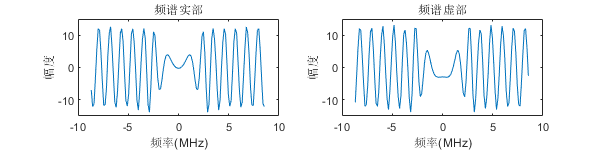

% 参数设置
TBP = 100;             % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
t_0 = 1e-6;            % 脉冲回波时延
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.25;       % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2+t_0:dt:T/2+t_0-dt;             % 时间变量
f = -F/2:df:F/2-df;                     % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);                 % Chirp信号复数表达式
srt = exp(1j*pi*K*(t-t_0).^2);          % Chirp信号时延表达式
Srf = fft(srt);                         % Chirp信号频谱表达式
Hf = exp(1j*pi*f.^2/K);                 % 频域匹配滤波器
Soutf = Srf.*Hf;                        % 匹配滤波器输出
% 绘图
H = figure;
set(H,'position',[100,100,600,150]);
subplot(121),plot(f*1e-6,real(Soutf))
axis([-10 10,-15 15])
title('频谱实部'),xlabel('频率(MHz)'),ylabel('幅度')
subplot(122),plot(f*1e-6,imag(Soutf))
axis([-10 10,-15 15])
title('频谱虚部'),xlabel('频率(MHz)'),ylabel('幅度')

% suptitle('图3.9 匹配滤波后的信号频谱')

#### 非基带信号

设$t_c$是脉冲中心相对于的时间偏移，则发射信号为：


$$s(t)=rect\left(\frac{t}{T}\right)\exp\{j\pi K(t-t_c)^2\}$$


则$t_0$时延后目标接收信号可表示为：


$$s_r(t) = rect\left(\frac{t-t_0}{T}\right)\exp\{j\pi K(t-t_c-t_0)^2\}
$$



$$s_r(t) = rect\left(\frac{t-t_0}{T}\right)\exp\{j\pi K(t-t_0)^2-j2\pi K(t-t_0)t_c+j\pi Kt_c^2\}
$$



$$f_c=-Kt_c
$$


使用驻定相位原理(POSP)，得到接收信号频谱近似为：


$$S_r(f)=rect\left(\frac{f+Kt_c}{|K|T}\right)\exp\left\{-j\pi\frac{f^2}{K}\right\}\exp\{-j2\pi f(t_0+t_c)\}$$


匹配滤波器在设计上应该能消除$S_r(f)$的二次相位，即为：


$$H(f)=rect\left(\frac{f+Kt_c}{|K|T}\right)\exp\left\{+j\pi\frac{f^2}{K}\right\}$$


注意，二次相位与目标位置$t_0$无关，如果有必要，也可将其消除，匹配滤波后的信号频谱为：


$$S_{out}(f)=S_r(f)H(f)=rect\left(\frac{f+Kt_c}{|K|T}\right)\exp\{-j2\pi f(t_0+t_c)\}$$


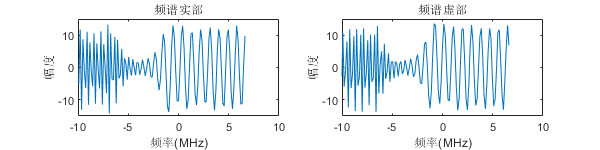

% 参数设置
TBP = 100;             % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
t_0 = 0;               % 脉冲回波时延
t_c = 1e-6;            % 时间偏移量
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.25;       % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2+t_0:dt:T/2+t_0-dt;             % 时间变量
f = -F/2-K*t_c:df:F/2-K*t_c-df;         % 频率变量
% 信号表达
st = exp(1j*pi*K*(t-t_c).^2);           % Chirp信号复数表达式
srt = exp(1j*pi*K*(t-t_c-t_0).^2);      % Chirp信号时延表达式
Srf = fft(srt);                         % Chirp信号频谱表达式
Hf = exp(1j*pi*f.^2/K);                 % 频域匹配滤波器
Soutf = Srf.*Hf;                        % 匹配滤波器输出
% 绘图
H = figure;
set(H,'position',[500,500,600,150]);
subplot(121),plot(f*1e-6,real(Soutf))
axis([-10 10,-15 15])
title('频谱实部'),xlabel('频率(MHz)'),ylabel('幅度')
subplot(122),plot(f*1e-6,imag(Soutf))
axis([-10 10,-15 15])
title('频谱虚部'),xlabel('频率(MHz)'),ylabel('幅度')

% suptitle('图3.9 匹配滤波后的信号频谱')

#### 窗效应

对频域匹配滤波器引入平滑窗，可以减少主瓣到旁瓣的能量泄露，降低峰值旁瓣比，但要以损失分辨率为代价，因为窗使压缩中的有效信号带宽变窄。

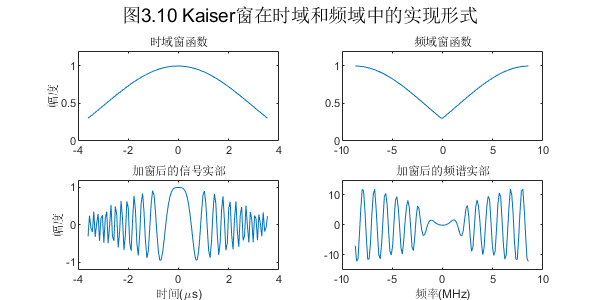

% 参数设置
TBP = 100;             % 时间带宽积
T = 7.2e-6;            % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha_os = 1.25;       % 过采样率，使用较高的过采样率是为了提高采样频率
F = alpha_os*B;        % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);           % Chirp信号复数表达式
Sf = fft((st));                   % Chirp信号频谱表达式
Hf = exp(1j*pi*f.^2/K);           % 频域匹配滤波器
Soutf = Sf.*Hf;                   % 匹配滤波器输出
% 窗函数
window = kaiser(N,2.5)';          % 时域窗
Window = fftshift(window);        % 频域窗
% 信号变换
st_window = window.*exp(1j*pi*K*t.^2);          % 加窗后的Chirp信号
Hf_Window = Window.*Hf;                         % 加窗后的频域匹配滤波器
Soutf_Window = Hf_Window.*Sf;                   % 加窗后的匹配滤波器输出
% 绘图
H = figure;
set(H,'position',[500,500,600,300]);
subplot(221),plot(t*1e+6,window)
axis([-4 4,0 1.2])
title('时域窗函数'),ylabel('幅度')
subplot(222),plot(f*1e-6,Window)
axis([-10 10,0 1.2])
title('频域窗函数')
subplot(223),plot(t*1e+6,real(st_window))
axis([-4 4,-1.2 1.2])
title('加窗后的信号实部'),xlabel('时间(\mus)'),ylabel('幅度')
subplot(224),plot(f*1e-6,real(Soutf_Window))
axis([-10 10,-15 15])
title('加窗后的频谱实部'),xlabel('频率(MHz)')
suptitle('图3.10 Kaiser窗在时域和频域中的实现形式')

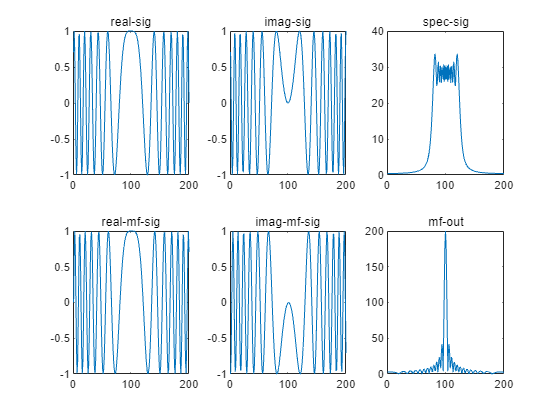

% 匹配滤波实例
clear all; 
%%%  parameters' definition 
c=3e+8;										% speed of light 
pi=3.1415926;  
j=sqrt(-1);	 
 
Tp=1.e-6; 								% transmitted pulse width       
fc=1.e+9;	 						   	% carrier frequency  
Br=50.e+6;              % transmitted bandwidth 
Fs=200.e+6;             % A/D sample rate 
kr=Br/Tp;               % range chirp rate 
 
Nr=Tp*Fs; 
Ni=1:Nr; 
tr=(Ni-Nr/2)*Tp/Nr; 
 
%=============================== 
%Generate a Chirp pulse 
%=============================== 
 
sig = exp(j*pi*kr*(tr).^2); 
 
figure;  
subplot(2,3,1); plot(real(sig));title('real-sig'); 
subplot(2,3,2); plot(imag(sig));title('imag-sig'); 
 
%=============================== 
% Spectrum of this Chirp pulse 
%=============================== 
 
sig_spec=fftshift(fft(sig)); 
subplot(2,3,3);  plot(abs(sig_spec));title('spec-sig'); 
 
%=============================== 
%Match filtering in time domain 
%=============================== 
 
mf_sig = conj(fliplr(sig)); 
subplot(2,3,4);  plot(real(mf_sig));title('real-mf-sig'); 
subplot(2,3,5);  plot(imag(mf_sig));title('imag-mf-sig'); 
 
mf_out = conv(sig, mf_sig); 
subplot(2,3,6);  plot(abs(mf_out(Nr/2+1:Nr*3/2)));title('mf-out'); 

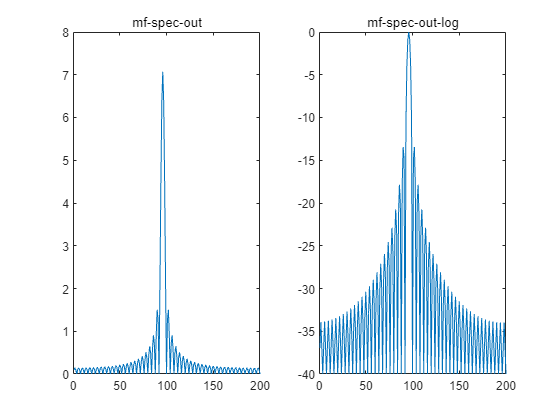

 
% pause; 
%===================================== 
%Match filtering in frequency domain 
%===================================== 
 
fr=(Ni-Nr/2)*Fs/Nr; 
mf_spec=exp(j*pi*fr.^2/kr); 
mf_spec_out=ifft(fftshift(sig_spec.*mf_spec)); 
 
figure;  
subplot(1,2,1); plot(abs(mf_spec_out));title('mf-spec-out'); 
 
sig_un=20*log10(abs(mf_spec_out)/max(abs(mf_spec_out))); 
for i=1:Nr 
    if (sig_un(i)<-40 ) 
        sig_un(i)=-40; 
    end  
end 
subplot(1,2,2); plot(sig_un);title('mf-spec-out-log'); 

提取冲击响应宽度

function [irw,locleft,locright] = get_irw(Af)
    % 找到Af的最大位置
    [~,locmax] = max(Af);
    % 找到locmax左边最接近-3dB的位置
    [~,locleft] = min(abs(Af(1:locmax-1)/max(abs(Af(1:locmax-1)))-0.707));
    % 找到locmax右边最接近-3dB的位置
    [~,locright] = min(abs(Af(locmax+1:end)/max(abs(Af(locmax+1:end)))-0.707));
    locright = locright + locmax;
    % 得到3dB波束宽度
    irw = locright-locleft;
end

提取峰值旁瓣比

function [pslr] = get_pslr(Af)
    % 找到所有的pesks
    peaks = findpeaks(Af);
    % 对peaks进行降序排列
    peaks = sort(peaks,'descend');
    % 得到第一旁瓣
    pslr = peaks(2);
end